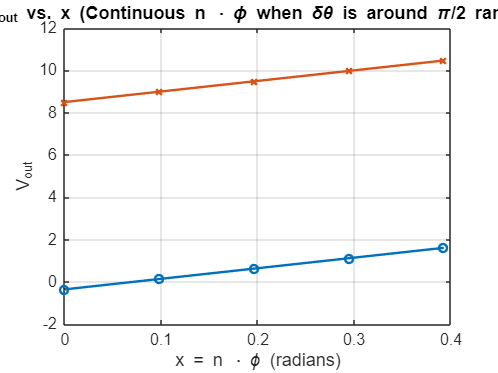

clear; clc;
 
 
 
 
phi = pi / 32;
%
% V_neg1 = cos(1.5 - phi);
% V_0 = cos(1.5);
% V_1 = cos(1.5 + phi);
%
% ABk = 2*(V_1 - V_neg1) / phi;
ABk=-10;
 
 
% delta_theta = pi/2 - (2 * V_0 / ABk);
 
 
 
 
x_values = (0:4) * pi/32;
Vout_pio2_values = zeros(size(x_values));
 
 
dth=1.5;
for i = 1:length(x_values)
    x = x_values(i);
    Vout_zero_values(i) = 1 - (ABk / 2) * (dth + x);
    Vout_pio2_values(i) = - (ABk / 2) * (dth + x-pi/2);
end
 
 
 
 
figure;
plot(x_values, Vout_pio2_values, '-o', 'LineWidth', 1.5, 'MarkerSize', 5);
hold on
plot(x_values, Vout_zero_values, '-x', 'LineWidth', 1.5, 'MarkerSize', 5);
 
 
 
 
xlabel('x = n \cdot \phi (radians)');
ylabel('V_{out}');
title('V_{out} vs. x (Continuous n \cdot \phi when \delta\theta is around \pi/2 range)');
grid on;